clc;
clear all;
x=linspace(0,3,61);
C=0.5;
const=4/14;
d1=digits;
digits(4);
prompt=input('(ArtificialViscosityCoefficient)Cx:');
Cx=prompt;
prompt=input('(ArtificialViscosityCoefficient)Cy:');
Cy=prompt;
for i=1:61
     A(i)=1+2.2*((x(i)-1.5)^2);
     if i<11 || i==11
        D(i)=1;
        T(i)=1;
     elseif i>11 && i<32
        D(i)=1-0.366*(x(i)-0.5);
        T(i)=1-0.167*(x(i)-0.5);
     elseif i>31 && i<44
        D(i)=0.634-0.702*(x(i)-1.5);
        T(i)=0.833-0.4908*(x(i)-1.5); 
     else
        D(i)=0.5892+0.10228*(x(i)-2.1);  
        T(i)=0.93968-0.0622*(x(i)-1.1);
     end
     V(i)=0.59/(D(i)*A(i));
     p(i)=D(i)*T(i);
     U1(i)=D(i)*A(i);
     U2(i)=D(i)*A(i)*V(i);
     U3(i)=D(i)*A(i)*(T(i)*2.5+0.7*(V(i)^2));
     F1(i)=U2(i);
     temp=U2(i)^2/U1(i);
     F2(i)=temp+const*(U3(i)-0.7*temp);
     F3(i)=(1.4*U2(i)*U3(i)/U1(i))-0.28*((U2(i)^3)/(U1(i)^2));
end
for i=1:61
    del_t(i)=C*(0.1/((T(i)^0.5)+V(i)));
end
t_step=min(del_t);
Net=[transpose(x) transpose(A) transpose(D) transpose(V) transpose(T) transpose(p) transpose(U1) transpose(U2) transpose(U3)];
disp(Net);

         0    5.9500    1.0000    0.0992    1.0000    1.0000    5.9500    0.5900   14.9160
    0.0500    5.6255    1.0000    0.1049    1.0000    1.0000    5.6255    0.5900   14.1071
    0.1000    5.3120    1.0000    0.1111    1.0000    1.0000    5.3120    0.5900   13.3259
    0.1500    5.0095    1.0000    0.1178    1.0000    1.0000    5.0095    0.5900   12.5724
    0.2000    4.7180    1.0000    0.1251    1.0000    1.0000    4.7180    0.5900   11.8466
    0.2500    4.4375    1.0000    0.1330    1.0000    1.0000    4.4375    0.5900   11.1487
    0.3000    4.1680    1.0000    0.1416    1.0000    1.0000    4.1680    0.5900   10.4785
    0.3500    3.9095    1.0000    0.1509    1.0000    1.0000    3.9095    0.5900    9.8361
    0.4000    3.6620    1.0000    0.1611    1.0000    1.0000    3.6620    0.5900    9.2215
    0.4500    3.4255    1.0000    0.1722    1.0000    1.0000    3.4255    0.5900    8.6349
    0.5000    3.2000    1.0000    0.1844    1.0000    1.0000    3.2000    0.5900    8.0761

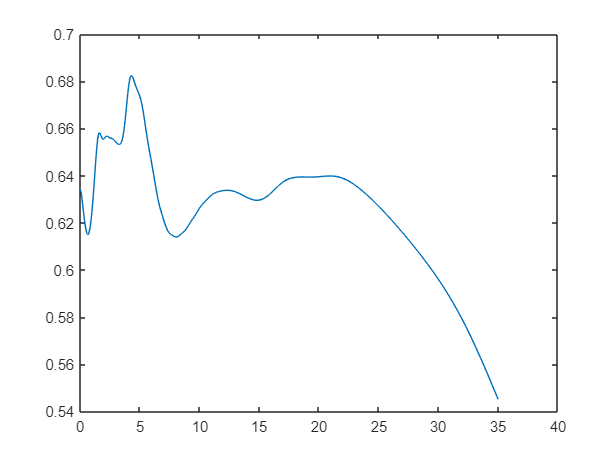

count=2;
timestep(1)=0;
density(1)=D(31);
massflow(1)=D(31)*V(31)*A(31);
t=0;
while(t<35)
 [dU1_dt,dU2_dt,dU3_dt,U1_p,U2_p,U3_p,F1_p,F2_p,F3_p,D_p,T_p,p_p]=predictor(F1,F2,F3,U1,U2,U3,D,t_step,const,A,T,p,Cx);
 [dU1_dtc,dU2_dtc,dU3_dtc,AV1,AV2,AV3]=corrector(F1_p,F2_p,F3_p,D_p,T_p,A,p_p,Cx,U1_p,U2_p,U3_p);
 dU1_dtavg=(dU1_dt+dU1_dtc)/2;
 dU2_dtavg=(dU2_dt+dU2_dtc)/2;
 dU3_dtavg=(dU3_dt+dU3_dtc)/2;
 for i=2:60
  U1(i)=U1(i)+dU1_dtavg(i)*t_step+AV1(i);
  U2(i)=U2(i)+dU2_dtavg(i)*t_step+AV2(i);
  U3(i)=U3(i)+dU3_dtavg(i)*t_step+AV3(i);
  D(i)=U1(i)/A(i);
  V(i)=U2(i)/U1(i);
  T(i)=0.4*((U3(i)/U1(i))-0.7*V(i)^2);
  p(i)=D(i)*T(i);
  F1(i)=U2(i);
  temp=U2(i)^2/U1(i);
  F2(i)=temp+const*(U3(i)-0.7*temp);
  F3(i)=(1.4*U2(i)*U3(i)/U1(i))-0.28*((U2(i)^3)/(U1(i)^2));
 end
 U2(1)=2*U2(2)-U2(3);
 V(1)=U2(1)/U1(1);
 U3(1)=U1(1)*(T(1)*2.5+0.7*(V(1)^2));
 U1(61)=2*U1(60)-U1(59);
 U2(61)=2*U2(60)-U2(59);
 V(61)=U2(61)/U1(61);
 D(61)=U1(61)/A(61);
 U3(61)=p(61)*A(61)*2.5+0.7*U2(61)*V(61);
 T(61)=0.4*((U3(61)/U1(61))-0.7*V(61)^2);
 F1(1)=U2(1);
 temp1=U2(1)^2/U1(1);
 F2(1)=temp1+const*(U3(1)-0.7*temp1);
 F3(1)=(1.4*U2(1)*U3(1)/U1(1))-0.28*((U2(1)^3)/(U1(1)^2));
 F1(61)=U2(61);
 temp61=U2(61)^2/U1(61);
 F2(61)=temp61+const*(U3(61)-0.7*temp61);
 F3(61)=(1.4*U2(61)*U3(61)/U1(61))-0.28*((U2(61)^3)/(U1(61)^2));
 %Net=[transpose(x) transpose(A) transpose(D) transpose(V) transpose(T) transpose(p) transpose(U1) transpose(U2) transpose(U3)];
 %disp(Net);
 t=t+t_step;
 timestep(count)=t;
 density(count)=D(31);

 massflow(count)=D(31)*V(31)*A(31);
 count=count+1;
end
plot(timestep,density);

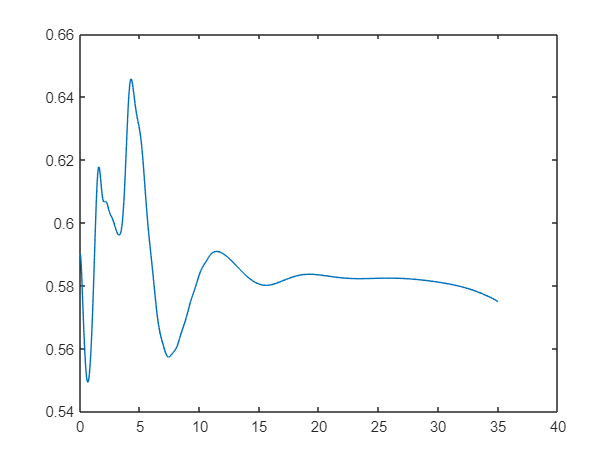

plot(timestep,massflow);

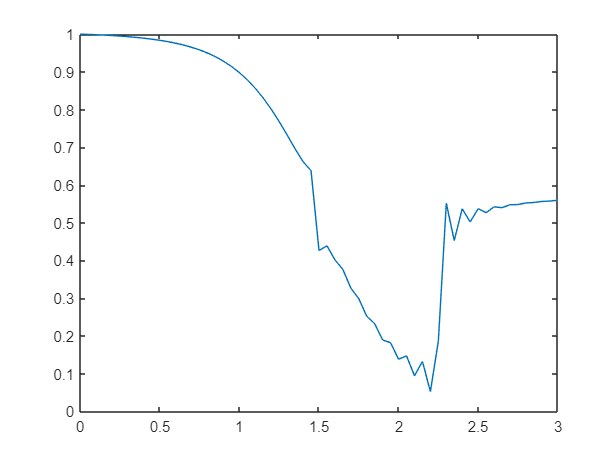

plot(x,p);

for i=1:61
    mf(i)=D(i)*V(i)*A(i);
end
Net=[transpose(x) transpose(A) transpose(D) transpose(V) transpose(T) transpose(p) transpose(U1) transpose(U2) transpose(U3)];
disp(Net);

         0    5.9500    1.0000    0.0976    1.0000    1.0000    5.9500    0.5805   14.9146
    0.0500    5.6255    0.9995    0.1033    0.9998    0.9992    5.6225    0.5805   14.0950
    0.1000    5.3120    0.9988    0.1094    0.9995    0.9983    5.3057    0.5805   13.3024
    0.1500    5.0095    0.9981    0.1161    0.9992    0.9973    4.9999    0.5805   12.5373
    0.2000    4.7180    0.9972    0.1234    0.9989    0.9961    4.7049    0.5805   11.7995
    0.2500    4.4375    0.9963    0.1313    0.9985    0.9948    4.4209    0.5805   11.0889
    0.3000    4.1680    0.9951    0.1400    0.9981    0.9932    4.1476    0.5805   10.4056
    0.3500    3.9095    0.9938    0.1494    0.9975    0.9913    3.8852    0.5804    9.7494
    0.4000    3.6620    0.9922    0.1597    0.9969    0.9891    3.6334    0.5804    9.1202
    0.4500    3.4255    0.9904    0.1711    0.9961    0.9866    3.3926    0.5804    8.5181
    0.5000    3.2000    0.9882    0.1835    0.9953    0.9835    3.1623    0.5803    7.9429

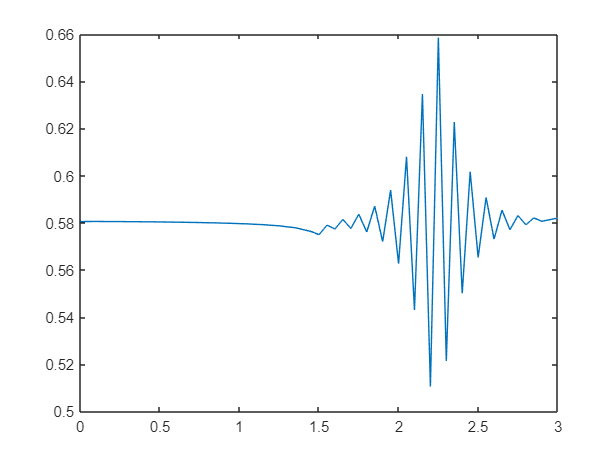

plot(x,mf);

g=[transpose(x) transpose(mf)]

g =          0    0.5805
    0.0500    0.5805
    0.1000    0.5805
    0.1500    0.5805
    0.2000    0.5805
    0.2500    0.5805
    0.3000    0.5805
    0.3500    0.5804
    0.4000    0.5804
    0.4500    0.5804


 function [dU1_dt,dU2_dt,dU3_dt,U1_p,U2_p,U3_p,F1_p,F2_p,F3_p,D_p,T_p,p_p]=predictor(F1,F2,F3,U1,U2,U3,D,t_step,const,A,T,p,Cx)
   U1_p(1)=U1(1);
   U2_p(1)=U2(1);
   U3_p(1)=U3(1);
   F1_p(1)=F1(1);
   F2_p(1)=F2(1);
   F3_p(1)=F3(1);
   D_p(1)=D(1);
   T_p(1)=T(1);
   p_p(1)=p(1);
   for i=2:60
       dU1_dt(i)=-(F1(i+1)-F1(i))/0.1;
       dU2_dt(i)=-((F2(i+1)-F2(i))/0.1)+(1/1.4)*D(i)*T(i)*((A(i+1)-A(i))/0.1);
       dU3_dt(i)=-(F3(i+1)-F3(i))/0.1;
       AVterm1=abs(p(i+1)-2*p(i)+p(i-1))*Cx;
       AVterm2=p(i+1)+2*p(i)+p(i-1);
       AV1=AVterm1*(U1(i+1)-2*U1(i)+U1(i-1))/AVterm2;
       AV2=AVterm1*(U2(i+1)-2*U2(i)+U2(i-1))/AVterm2;
       AV3=AVterm1*(U3(i+1)-2*U3(i)+U3(i-1))/AVterm2;
       U1_p(i)=U1(i)+(dU1_dt(i)*t_step)+AV1;
       U2_p(i)=U2(i)+(dU2_dt(i)*t_step)+AV2;
       U3_p(i)=U3(i)+(dU3_dt(i)*t_step)+AV3;
       F1_p(i)=U2_p(i);
       temp1=U2_p(i)^2/U1_p(i);
       F2_p(i)=temp1+const*(U3_p(i)-0.7*temp1);
       F3_p(i)=(1.4*U2_p(i)*U3_p(i)/U1_p(i))-0.28*((U2_p(i)^3)/(U1_p(i)^2));
       D_p(i)=U1_p(i)/A(i);
       T_p(i)=0.4*((U3_p(i)/U1_p(i))-0.7*(U2_p(i)/U1_p(i))^2);
       p_p(i)=D_p(i)*T_p(i);
   end
   U1_p(61)=U1(61);
   U2_p(61)=U2(61);
   U3_p(61)=U3(61);
   F1_p(61)=F1(61);
   F2_p(61)=F2(61);
   F3_p(61)=F3(61);
   D_p(61)=D(61);
   T_p(61)=T(61);
   p_p(61)=p(61);
end
function [dU1_dtc,dU2_dtc,dU3_dtc,AV1,AV2,AV3]=corrector(F1_p,F2_p,F3_p,D_p,T_p,A,p_p,Cx,U1_p,U2_p,U3_p)
   AV1(1)=0;
   AV2(2)=0;
   AV3(1)=0;
   for i=2:60
       dU1_dtc(i)=-(F1_p(i)-F1_p(i-1))/0.1;
       dU2_dtc(i)=-((F2_p(i)-F2_p(i-1))/0.1)+(1/1.4)*D_p(i)*T_p(i)*((A(i)-A(i-1))/0.1);
       dU3_dtc(i)=-(F3_p(i)-F3_p(i-1))/0.1;
       AVc1=abs(p_p(i+1)-2*p_p(i)+p_p(i-1))*Cx;
       AVc2=p_p(i+1)+2*p_p(i)+p_p(i-1);
       AV1(i)=AVc1*(U1_p(i+1)-2*U1_p(i)+U1_p(i-1))/AVc2;
       AV2(i)=AVc1*(U2_p(i+1)-2*U2_p(i)+U2_p(i-1))/AVc2;
       AV3(i)=AVc1*(U3_p(i+1)-2*U3_p(i)+U3_p(i-1))/AVc2;
   end
end
     